y = [0, 3, 3, 0, -3, 0];
x = [1, 0, 3, 5, 3, 8];


path = Path(x,y,0.5);

obj =   Path with properties:

         startPoint: [1×1 struct]
           endPoint: [1×1 struct]
        transitions: [10×1 double]
         subsplines: [1×9 Spline]
    maxAbsCurvature: [1×1 struct]
             length: 18.3090


len = path.length

len = 18.3090

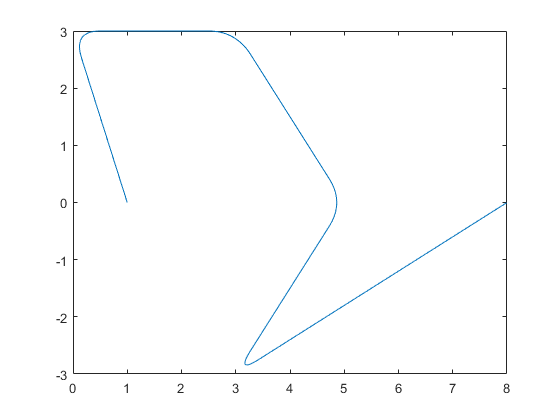

s = [0:1e-2:len];
[x,y] = path.getPoint(s);
[x1,y1] = path.diff(s);
[x2,y2] = path.diff(s,2);
%[kx, ky] = path.getMaxSegmentCurvature(s)


figure();
plot(x,y)

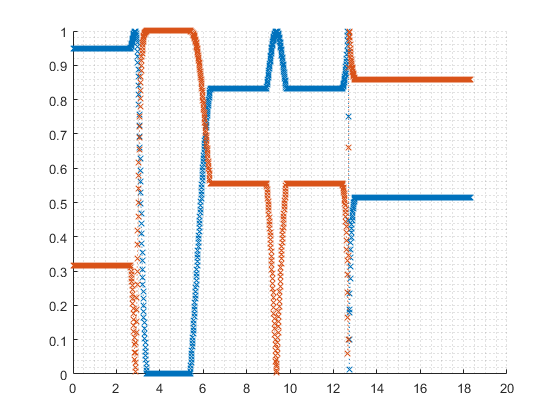

figure();
%plot(s,x1, ":x");
hold on
%plot(s,y1, ":x");
plot(s, abs(y1),":x")
plot(s, abs(x1),":x")
grid minor


%figure()
%plot(s, atan2d(y1,x1))

planner = TrajectoryPlannerSimple(path, 1,1);


planner = planner.generateTrajectory(0.01);

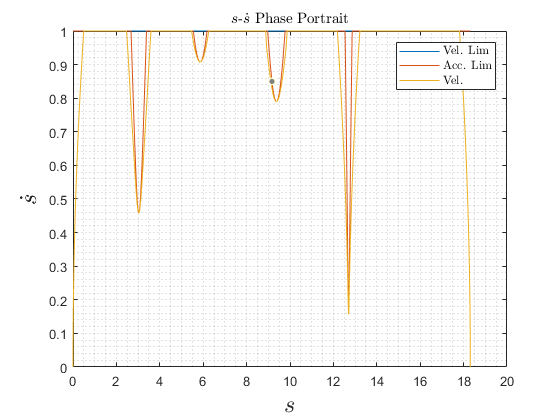

planner.plotVelLim(true)

%plot(planner.posBackward, planner.velBackward)


swp = path.getDiscontinuousSwitchtingPointCandidate()

swp =     2.6623
    3.4005
    5.4005
    6.2774



ds = 1e-4;
s0 = swp(1);
sm = s0-ds;
sp = s0+ds;

[~, ~, velMaxAcc]  = planner.velMax([sm sp]);

velMaxAccM = velMaxAcc(1);
velMaxAccP = velMaxAcc(2);
dvelMaxAccM = dvelMaxAccFunc(sm, planner)

dvelMaxAccM = 0

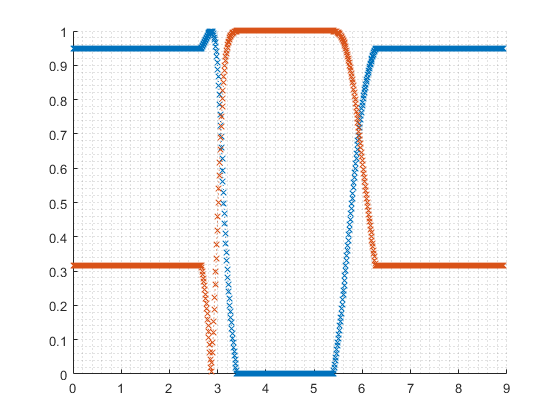

dvelMaxAccP = 0

dvelMaxAccP = dvelMaxAccFunc(sp, planner)


[~, accMax] = planner.accLim([sm sp], [velMaxAccM velMaxAccP]) ;
accMaxM = accMax(1)

accMaxM = 1

accMaxP = accMax(2)

accMaxP = 0.3151


%eq (38)
foundSWP = (velMaxAccM < velMaxAccP && accMaxM >= dvelMaxAccM) || ...
(velMaxAccM > velMaxAccP && accMaxP <= dvelMaxAccP)

foundSWP = logical
   0


swp = path.getContinousSwitchingPointCandiate()

ds = 1e-4;
s0 = swp(1);
sm = s0-ds;
sp = s0+ds;
[velMax, ~, velMaxAcc]  = planner.velMax([sm s0 sp]);
dvelMaxAcc = diff(velMaxAcc)/ds;
dvelMaxAccM = dvelMaxAccFunc(sm, planner);
dvelMaxAccP = dvelMaxAccFunc(sp, planner);

foundSWP = dvelMaxAccM < 0 && dvelMaxAccP > 0

planner.getContinuousVelocitySwitchingPoints()
ds = 1e-3;
s0 = swp(1);
sm = s0-ds;
sp = s0+ds;

[velMax, ~, velMaxAcc]  = planner.velMax([sm sp]);


swp = path.getDiscontinuousSwitchtingPointCandidate()
ds = 1e-3;
s0 = swp(2);
sm = s0-ds;
sp = s0+ds;

[velMax, ~, ~]  = planner.velMax([sm sp]);
[accMin]  = planner.accLim([sm sp], [velMax(1), velMax(2)]);
dvelMaxAccM = dvelMaxAccFunc(sm,planner)
dvelMaxAccP = dvelMaxAccFunc(sp, planner)


(accMin(1) > dvelMaxAccM) && (accMin(2) < dvelMaxAccP)



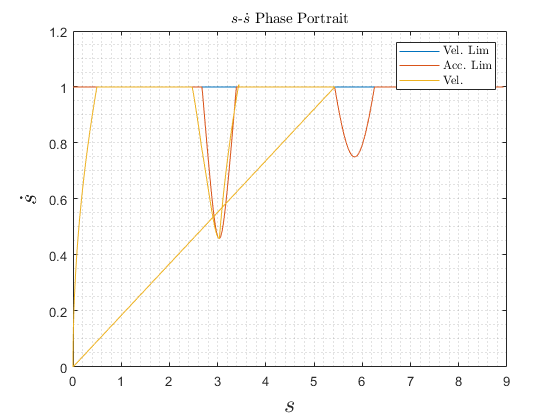

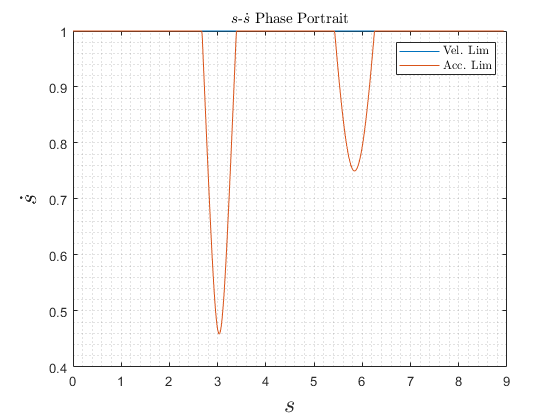

%planner = planner.generateTrajectory(0.01)
planner.plotVelLim()

[velMax, dvelMax, velMaxAcc] = planner.velMax(s);
vel = min(velMax, velMaxAcc); 
[accMin, accMax] = planner.accLim(s, velMaxAcc)
dvelMaxAccFunc(3.029,planner)
% hold on
figure()
plot(s)
hold on;
plot(s, accMax)

#### **Switching Points**

%VII. A. 1) Caused by Acceleration Constraints and Discontinuous
s = [0:0.001:path.length] 
tol = 0.04;
idx = find((abs(diff(velMaxAcc)) > tol) == 1, 1,"first")
sp = s(idx+2);
sm = s(idx);

[~, dvelMaxP, velMaxAccP]     = planner.velMax([s(idx+1), sp])
[~, dvelMaxM, velMacAccM]     = planner.velMax([sm ,s(idx+1)])
[~, accMaxP]                  = planner.accLim(sp, velMaxAccP)
[~, accMaxM]                  = planner.accLim(sm, velMacAccM)

dvelMaxAccP = diff(velMaxAccP)./diff([s(idx+1), sp])
dvelMacAccM = diff(velMacAccM)./diff([sm ,s(idx+1)])

velMaxAccP = velMaxAccP(2);
velMacAccM = velMacAccM(1);

foundSwitchingPoint = ((velMacAccM < velMaxAccP) & (accMaxM >= dvelMacAccM)) | ((velMacAccM > velMaxAccP) & (accMaxP <= dvelMaxAccP))
ssw = s(idx+1)

%VII. A. 2) Caused by Acceleration Constraints and Continuous and Nondifferentiable

idxY = find(diff(sign(dfy(s, path))) ~= 0, 1, "first") 
idxX = find(diff(sign(dfx(s, path))) ~= 0, 1, "first") 

if ~isempty(idxY) 
    sy = fzero(@(s)dfy(s,path), [s(idxY-10) s(idxY+10)])
    foundSwitchingPoint = length(sy) ~= 0
end

if length(idxX) ~= 0
    sx = fzero(@(s)dfx(s,path), [s(idxX-10) s(idxX+10)])
    foundSwitchingPoint = length(sx) ~= 0
end


%VII. A. 2) B. Caused by Velocity Constraints and Continuous
% idx = find(diff(sign(swPointContVel(s,planner))) ~= 0) 
% s(idx+1)
% foundSwitchingPoint = length(s(idx+1)) ~= 0
figure()


%VII. A. 2) B. Caused by Velocity Constraints and Discontinuous
[ddx, ddy] = path.diff(s, 2);
tol = 0.3;
idx = find((abs(diff(ddx)) > tol) == 1, 1,"first")

[velMaxM, ~, velMaxAccM]         = planner.velMax([s(idx) s(idx+1)]);
[velMaxP, ~, velMacAccP]         = planner.velMax([s(idx+1) s(idx+2)]);
[accMinM, ~]                     = planner.accLim(s(idx+1), velMaxM);
[accMinP, ~]                     = planner.accLim(s(idx+1), velMaxP);

foundSwitchingPoint = (accMinM >= diff(velMaxAccM)) & (accMinP <= diff(velMacAccP))

idx = find((abs(diff(ddy)) > tol) == 1, 1,"first")
[velMaxM, ~, velMaxAccM]         = planner.velMax([s(idx) s(idx+1)]);
[velMaxP, ~, velMacAccP]         = planner.velMax([s(idx+1) s(idx+2)]);
[accMinM, ~]                     = planner.accLim(s(idx+1), velMaxM);
[accMinP, ~]                     = planner.accLim(s(idx+1), velMaxP);

foundSwitchingPoint = (accMinM >= diff(velMaxAccM)) & (accMinP <= diff(velMacAccP))


## Backward Integration crossing point search

x1 = [[0:0.01:4],zeros(1,1000) ]
y1 = x1.^2;

x2 =[4.5:-0.0133:2];
y2 = (x2-4.5).^2;

figure();
plot(x1, y1,":x")
hold on
plot(x2, y2,":x")

for i = 1:length(x2)
    idx1 = find(x2(i) < x1, 1, "first");
    if(y2(i) > y1(idx1))
        idx2 = i;
        break;
    end
end
length(y1)
x1(idx1:idx1+idx2-2) = flip(x2(1:idx2-1))
y1(idx1:idx1+idx2-2) = flip(y2(1:idx2-1))
figure()
plot(x1,y1,"--x")

function swPointContVel = swPointContVel(s, planner)
        [valMax, ~, velMaxAcc] = planner.velMax(s);
        [accMin, ~]  = planner.accLim(s, valMax);
        dvelMaxAcc  =diff([0; velMaxAcc]);
        swPointContVel  = accMin -dvelMaxAcc;       
end

function ret = dvelMaxAccFunc(s, planner)
      ds  = 1e-6;
     [~, ~, velMaxAcc] = planner.velMax([s-ds, s+ds]);
     ret = diff(velMaxAcc)/(2*ds);
end